**Part 2:** Produce 2D arrays of the specified function(s) via the specified method(s) and produce appropriate graph(s) *in another figure*.

Generate these functions:

- 
$$\mathrm{exp}\left(-x^2 -y^2 \right)$$


- $\cos \left(3\theta \right)\left(r-r^3 \right)\;\exp \left(-r^2 \right)$, where $\left(r,\theta \right)$are polar coordinates but plot in (x,y) space.HINT: you may use [atan2 (Links to an external site.)](https://au.mathworks.com/help/matlab/ref/atan2.html) or [angle. (Links to an external site.)](https://au.mathworks.com/help/matlab/ref/angle.html)

Demonstrate these methods at least once each:

- nested loops

- meshgrid *or* broadcasting

Show these plots once each:

- A top-down plot

- A 3D plot

Make sure that all plots are carefully presented to allow a full understanding of the results.

clc;
clear;

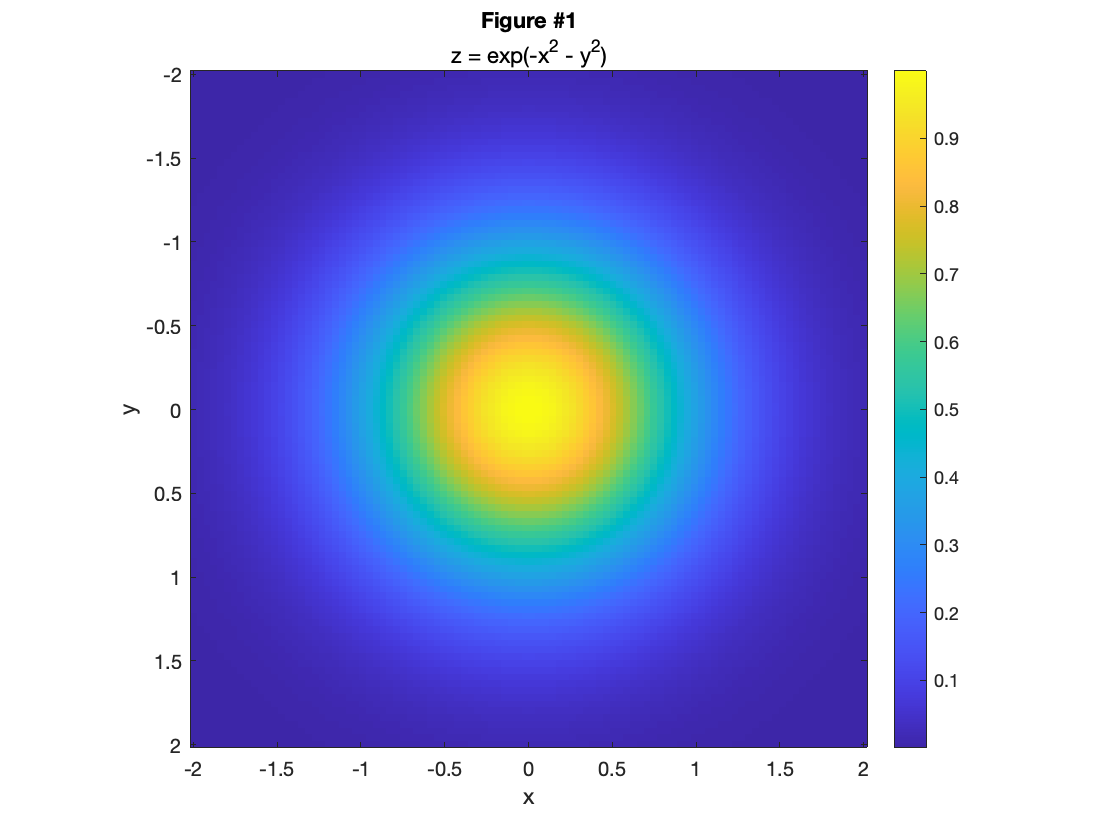

% Broadcasting and top-down plot
x1 = linspace(-2, 2);
y1 = linspace(-2, 2).';
z1 = exp(-x1.^2 - y1.^2); % broadcasting

imagesc(x1, y1, z1);
colorbar
axis('image')
subtitle('z = exp(-x^2 - y^2)')
xlabel('x')
ylabel('y')
title('Figure #1')

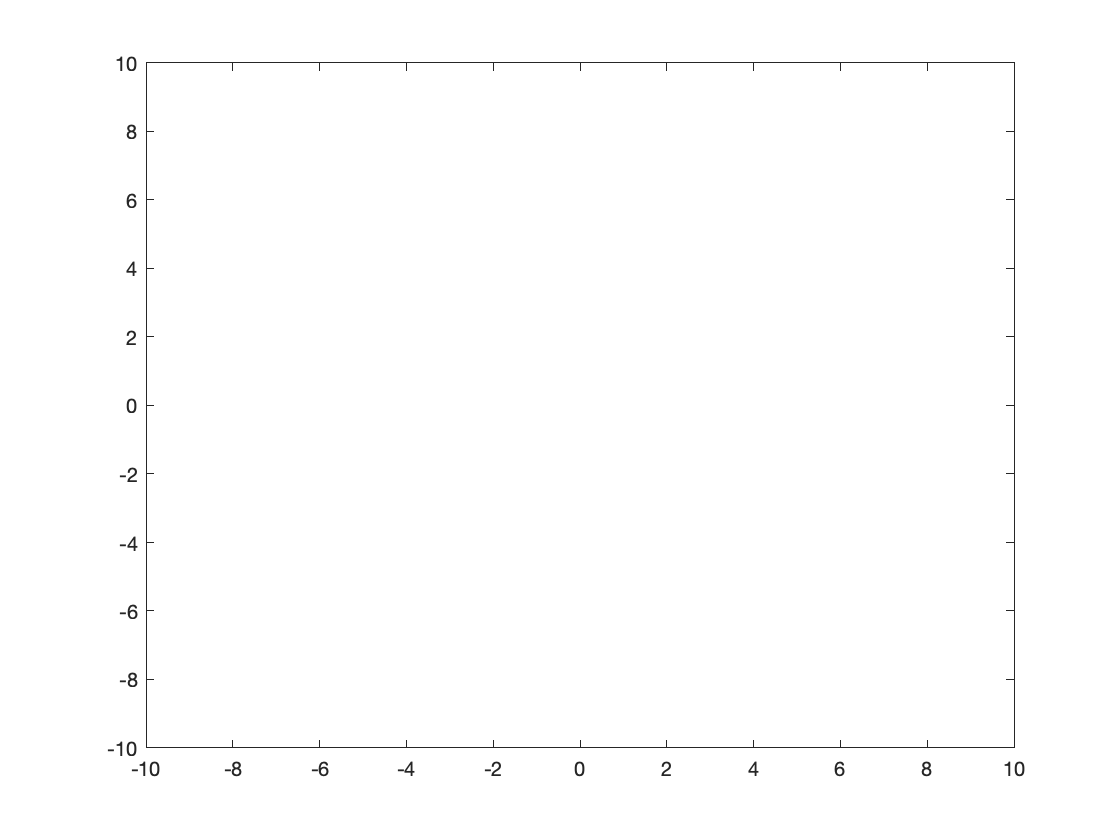

% Polar Coordinates and 3D-plot
r = linspace(-10, 10);
theta = linspace(-10, 10);
z = nan(length(r));

for i = 1:length(r)
    z(i) = cos(3.*theta(i) .* (r(i) - r(i).^3) * exp(-r(i).^2));
end

contour(r, theta, z);